# The Idea for the project

The idea of the project is to develop an interactive code that will ask some demographics questions to the participants who will come for one of my future projects. 

There will be three parts of this project:

- A pre-session questionnaires, such as: name, address, contact information (email or mobile), handedness, if the participant has movement disorder then his/her diagnosis, any allergies. These form will be obtain before the experiment. The participants will be given random number in this step which will be used to store all their experimental data. 

- A video demostration during session using MATLAB Robotics Toolbox.

- A post-session survey to know if they were comfortable using the wearable robot, and using the interactive robot; Kinova Gen3 7Dof robot.

# Pre-session questionnaires

Here I am developing a demographics form for human participants who will come to the lab for experiments. I will start by asking questions like their name, address, email, and phone no, later questions can be added in this form such as age, handedness, and if they are on any medication or have any known allergies. I am starting with only name, address, email, and phone. I will use conditions like name, address, email, and number that can not be empty input, numbers have to be a ten-digit number. Also, the participants will be asked to verify the information before saving it to the Excel file. The information will be saved automatically with each run. The participants will be assigned a participant number, which will be used in the post-session survey to make sure that the survey doesn't have their personal information.

clear all
close all
commandwindow
clc

% Create a new Excel file
col_header={'Participant No', 'Date and time', 'Name', 'Address', 'Email', 'Phone No'};
% %lets consider 10 participants so, generating 10 random numbers as the
% participants numbers
n = 10; 
N = randperm(99, n)

N =     85    64    37    19    41    46    12    55    21    35


N_s = num2str (N)

N_s = '85  64  37  19  41  46  12  55  21  35'

If this excel file doesn't exist in the current directory this code will generate a new file. But this file is already available, this code will take the inputs (name, email address and phone) and add them in the pre-existing file as a new line. 


excelFileName = xlswrite('Participants Information.xls',col_header,'Sheet1','A1');  %Write column header

sheet =1;
excelFile = 'Participants Information.xls';

xlswrite(excelFile,N',sheet,'A2')
% Specify the Excel file
data = readtable('Participants Information.xls', 'PreserveVariableNames', true)

data = 10×6 table
    Participant No    Date and time       Name           Address                 Email                Phone No 
    ______________    _____________    ___________    _____________    __________________________    __________

          85               NaN         {'Nusaiba'}    {'Riverside'}    {'nusaibahafiz@gmail.com'}    9.5154e+09
          64               NaN         {0×0 char }    {0×0 char   }    {0×0 char                }           NaN
          37               NaN         {0×0 char }    {0×0 char   }    {0×0 char                }           NaN
          19               NaN         {0×0 char }    {0×0 char   }    {0×0 char                }           NaN
          41               NaN         {0×0 char }    {0×0 char   }    {0×0 char                }        

%% Checking if the file I want to use is in the current directory
%HomeFolder=cd('C:/Users/nusai/Downloads');
pwd

ans = 'C:\Users\bioniclab\Downloads'


ls


.                                                                                                                                   ..                                                                                                                                  .gitattributes                                                                                                                      .gitignore                                                                                                                          220669-participant-survey.pdf                                                                                                       28166-Article Text-32220-1-2-20240324.pdf                                                                                           978-3-319-32552-1.pdf                                                                                                               ATI delta DAQ sensor                                                       

% making sure there will nothing in the command window 
clear all
close all
commandwindow
clc
%% Taking inputs from participants as name, address, email and phone numbers
excelFile = 'Participants Information.xls';
sheet =1;

for i = 1:11
    [~,~,raw] = xlsread(excelFile);
    if ~isempty(find(isnan(raw{i,2})))
        fprintf('i is %d',i)
        xlRange = ['B' num2str(i)]
        firstColumn = ['A' num2str(i)]
        break
       %disp(' %s', num2str(i))
    end
end

i is 2

xlRange = 'B2'

firstColumn = 'A2'

% Automatically log the current date & time
dt = datetime('now','Format','yyyy-MM-dd HH:mm:ss');

confirmation = false;
while ~confirmation
    % Take character inputs from the user
    name_gotten=false;
    while name_gotten==false
        name = input('Hello, Please enter your name: ', 's');
        if ~isempty(name)
        name_gotten=true;
        else
        sprintf('Oops, be sure to type something. Don''t just hit the Enter key.')
        end
    end

    address_gotten=false;
    while address_gotten==false
        address = input('Please enter your address: ', 's');
        if ~isempty(address)
        address_gotten=true;
        else
        sprintf('Oops, be sure to type something. Don''t just hit the Enter key.')
        end
    end
    
    characters_bad=true;
    while characters_bad==true
     email=input ('Please enter your email (Make sure it has an @ sign): ','s');
     if ~contains(email,'@')
        disp(['Oops, I''m' ' not seeing a @'])
     else characters_bad=false;  % leave out for error!!!
     end
    end % while characters_bad==true

phone_no = false;
while phone_no==false
    phone = input('Please enter your phone number: ', 's');
    if isempty(phone) || ~isnumeric(str2double(phone)) || length(regexp(phone,'\d'))~=10
    disp('Invalid input. Make sure your phone number is a 10 digit number');
    else
        phone_no = true;
    disp('Looks good!!');
    end
end
    
    % Display the inputs to the user
    disp('------------------------------------------');
    disp('Confirm the following information:');
    disp(['Your name: ' name]);
    disp(['Address: ' address]);
    disp(['Email: ' email]);
    disp(['Phone: ' phone]);
    
    % Ask the user for confirmation
    user_response = input('Are the above information correct? (yes/no): ', 's');
    
    % Check user response
    if strcmpi(user_response, 'yes')
        confirmation = true;  % Set the flag to end the loop
    else
        disp('Please re-enter the information.');
    end
end

Looks good!!


------------------------------------------


Confirm the following information:


Your name: Nusaiba


Address: Riverside


Email: nusaibahafiz@gmail.com


Phone: 9515394734



% Convert character arrays to cell arrays
date = {datestr(dt,'yyyy-mm-dd HH:MM:SS')};
name = {name};
address = {address};
email = {email};
phone = {phone};

% Create a table with the user information
userInformation = [date,name, address, email, phone]

userInformation = 1×5 cell array
    {'2025-08-14 16:26:25'}    {'Nusaiba'}    {'Riverside'}    {'nusaibahafiz@gmail.com'}    {'9515394734'}



% Append the new user information to the existing data
xlswrite(excelFile,userInformation,sheet,xlRange);

% showing the updated table here
data = readtable('Participants Information.xls', 'PreserveVariableNames', true)

data = 10×6 table
    Participant No       Date and time           Name           Address                 Email                Phone No 
    ______________    ____________________    ___________    _____________    __________________________    __________

          85          14-Aug-2025 16:26:25    {'Nusaiba'}    {'Riverside'}    {'nusaibahafiz@gmail.com'}    9.5154e+09
          64                           NaT    {0×0 char }    {0×0 char   }    {0×0 char                }           NaN
          37                           NaT    {0×0 char }    {0×0 char   }    {0×0 char                }           NaN
          19                           NaT    {0×0 char }    {0×0 char   }    {0×0 char                }           NaN
          41                           NaT    {0×0 char }    {0

% Read data from the specified cell in the Excel file
participantsNo = xlsread(excelFile, sheet, firstColumn);

% Display the cell value to the user
disp(['Your participant number for this experiment is: ' num2str(participantsNo)]);

Your participant number for this experiment is: 85


I have saved only two participants information and gave them a participants number. This code can save upto 10 participants information in new rows from the last participant and gave them a random but unique participants number. 

# Video demostration during session using MATLAB Robotics Toolbox.

During session we can also show a video demostration of the motion of robot. I designed it using MATLAB Robotics Toolbox, where I asked the robot to draw a circle in the vertical plane. 

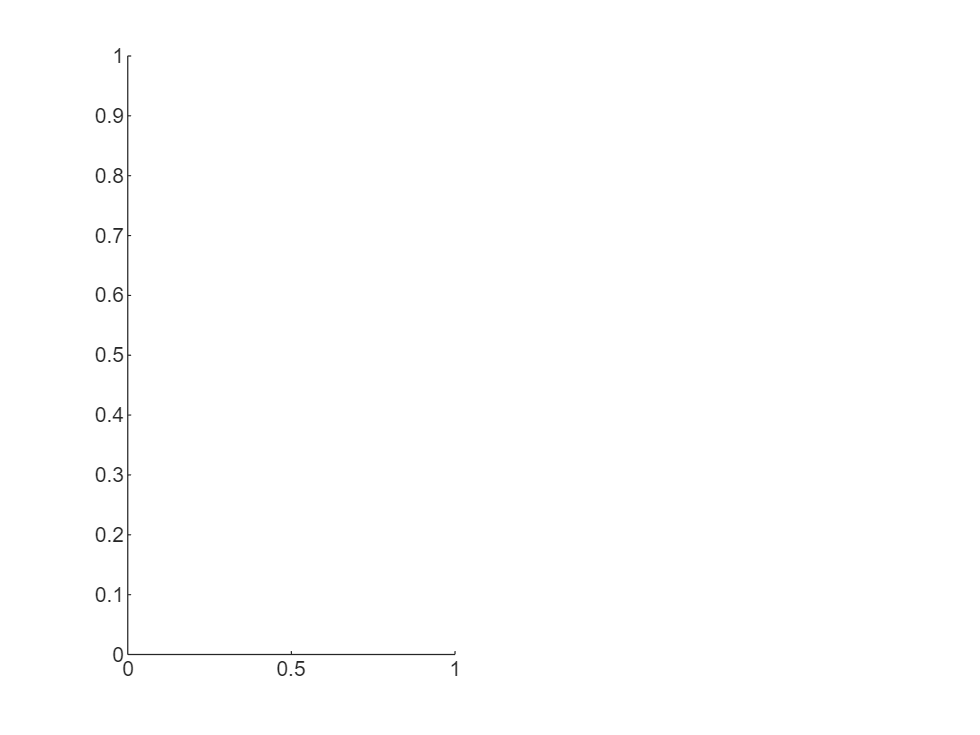

clc
clear all
close all

% getting the robot from robotic toolbox and defining position and
% end-effectors name
gen3 = loadrobot("kinovaGen3");
gen3.DataFormat = 'column';
q_home = [0 15 180 -130 0 55 90]'*pi/180; %home position
eeName = 'EndEffector_Link';
T_home = getTransform(gen3, q_home, eeName);

figure;
show(gen3,q_home);
drawFloor();
axis auto;
view([60,10]);
  axis on;
  xlim([-1,1]);
  ylim([-1,1]);
  zlim([-.5,1]);

%% Inverse Kinematics Solver and Set Parameters

ik = inverseKinematics('RigidBodyTree', gen3);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1, 1, 1, 1, 1, 1];
q_init = q_home;

%% Define Waypoints from the Desired Trajectory

center = [0.5 0 0.5]; %[x y z]
radius = 0.2;

dt = 0.25;
t = (0:dt:10)';
theta = t*(2*pi/t(end))-(pi/2);
points = center + radius*[0*ones(size(theta)) cos(theta) sin(theta)];

hold on;
plot3(points(:,1),points(:,2),points(:,3),'-*r', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');
axis auto;
view([60,10]);
grid('minor');

%% The Inverse Kinematics for Each Waypoint

numJoints = size(q_home,1);   
numWaypoints = size(points,1);
qs = zeros(numWaypoints,numJoints);
for i = 1:numWaypoints
    T_des = T_home;
    T_des(1:3,4) = points(i,:)';
    [q_sol, q_info] = ik(eeName, T_des, weights, q_init);
    
    % Display status of ik result
    %disp(q_info.Status);
    
    % Store the configuration
    qs(i,:) = q_sol(1:numJoints); 
    
    % Start from prior solution
    q_init = q_sol;
end

figure;
subplot(121)

    robot = imread("kinovaGen3.jpg");

Error using imread>get_full_filename (line 633)
Unable to find file "kinovaGen3_2.jpg".

Error in imread (line 395)
        fullname = get_full_filename(filename);

    imshow(robot)
    %imshow(robot,"Border","tight")
    axis off 
    title('The robot in the lab')
subplot(122)
% Visualize the Animation of the Solution
v = VideoWriter('Circle Trajecory','MPEG-4');
    open(v);

% figure; 
set(gcf,'Visible','on');
ax = show(gen3,qs(1,:)');
ax.CameraPositionMode='auto';
hold on;
 
% Plot waypoints
plot3(points(:,1),points(:,2),points(:,3),'-r','LineWidth',2);
axis auto;
view([60,10]);
grid('minor');
hold on;
 
title('Simulated Movement of the Robot');
% Animate
framesPerSecond = 10;
r = robotics.Rate(framesPerSecond);
for i = 1:numWaypoints
    show(gen3, qs(i,:)','PreservePlot',false);
    drawnow;
    drawFloor();
    waitfor(r);
    pause(.01);
   frame = getframe(gcf);
   writeVideo(v,frame);
end
close(v);


# Post Session Survey

In this section I am making a post session survey. The participants will be asked few questions such as, how they felt in this experiment, if the instruction was clear, if they are comfortable using the wearable soft robot that was placed on their arm, if the interaction robot functioned properly, if they liked the game they played. Their response will be saved in a excel file following their participant number. This excel fille will not contain any personal informations. I am using a "agree-disagree" scale, commonly known as Likert scale. It allows individuals to express their level of agreement or disagreement with the asked statement.

clear all
close all
commandwindow
clc

% Create a new Excel file
col_header={'Participant No','The instruction was clear', ...
    'Wearable robot was comfortable', 'Wearable robot helped me', ...
    'Kinova robot functioned properly', 'The game I played was nice'};

N = zeros(10,1)

excelFileName = xlswrite('Post Session Survey.xls',col_header,'Sheet1','A1');  %Write column header

sheet =1;
excelFile = 'Post Session Survey.xls';

xlswrite(excelFile,N,sheet,'A2')
   
% Seeing the excel file, I made a file for 10 participants' response
data = readtable('Post Session Survey.xls', 'PreserveVariableNames', true)

Here I will be checking the folder

HomeFolder=cd('C:\Users\nusai\Downloads\PSYC233')
pwd

ls

Now I wrote this following code to collect participants response. The code was written in a way that the participants will give their response as 1,2,3,4,5 following a statement meaning 

clear all
close all
commandwindow
clc

excelFile = 'Post Session Survey.xls';
sheet =1;

for i = 1:11
    [~,~,raw] = xlsread(excelFile);
    if ~isempty(find(isnan(raw{i,2})))
        fprintf('i is %d',i)
        xlRange = ['B' num2str(i)]
        firstColumn = ['A' num2str(i)]
        break
       %disp(' %s', num2str(i))
    end
end

confirmation = false;
while ~confirmation
    % Take character inputs from the user
    ID_gotten=false;
    while ID_gotten==false
        ID = input('Hello, Please enter your participant number: ', 's');
        % instructor can help in this stage by confirming the participants
        % number
        if ~isempty(ID)
        ID_gotten=true;
        else
        sprintf('Oops, be sure to type something. Don''t just hit the Enter key.')
        end
    end
% Display the inputs to the user
    disp('Here you will see few statement and let me know if you agree or disagree with them');
    disp('By your response the instrutors will understand how you felt in this experiment');
    disp('You need to provide your response using numbers 1 to 5');
    disp('1 = Strongly disagree, 2 = disgree, 3 = Neutral, 4 = Agree, 5 = Strongly agree');
    disp('Remember higher number indicates you are agreeing more with the given statement');

%1st resposne
    response_gotten = false;
while ~response_gotten
    response1 = input('The instruction was clear: ', 's');    
    % Convert the input to a numeric value
    numeric_response = str2double(response1);
    % Check if the input is empty or not a number or not within the specified range
    if isempty(response1) || isnan(numeric_response) || numeric_response < 1 || numeric_response > 5
        disp('Invalid input. Please enter a number from 1 to 5.');
    else
        response_gotten = true;
    end
end

%2nd resposne
    response_gotten = false;
while ~response_gotten
    response2 = input('Wearable robot was comfortable: ', 's');    
    % Convert the input to a numeric value
    numeric_response = str2double(response2);
    % Check if the input is empty or not a number or not within the specified range
    if isempty(response2) || isnan(numeric_response) || numeric_response < 1 || numeric_response > 5
        disp('Invalid input. Please enter a number from 1 to 5.');
    else
        response_gotten = true;
    end
end

%3rd resposne
    response_gotten = false;
while ~response_gotten
    response3 = input('Wearable robot helped me: ', 's');    
    % Convert the input to a numeric value
    numeric_response = str2double(response3);
    % Check if the input is empty or not a number or not within the specified range
    if isempty(response3) || isnan(numeric_response) || numeric_response < 1 || numeric_response > 5
        disp('Invalid input. Please enter a number from 1 to 5.');
    else
        response_gotten = true;
    end
end

%4th resposne
    response_gotten = false;
while ~response_gotten
    response4 = input('Kinova robot functioned properly: ', 's');    
    % Convert the input to a numeric value
    numeric_response = str2double(response4);
    % Check if the input is empty or not a number or not within the specified range
    if isempty(response4) || isnan(numeric_response) || numeric_response < 1 || numeric_response > 5
        disp('Invalid input. Please enter a number from 1 to 5.');
    else
        response_gotten = true;
    end
end

%5th resposne
    response_gotten = false;
while ~response_gotten
    response5 = input('The game I played was nice: ', 's');    
    % Convert the input to a numeric value
    numeric_response = str2double(response5);
    % Check if the input is empty or not a number or not within the specified range
    if isempty(response5) || isnan(numeric_response) || numeric_response < 1 || numeric_response > 5
        disp('Invalid input. Please enter a number from 1 to 5.');
    else
        response_gotten = true;
    end
end
    % Convert each character in the numeric scale to the corresponding label
    responses = [response1, response2, response3, response4, response5];
    agreeDisagreeScale = arrayfun(@AgreeDisagree, responses, 'UniformOutput', false);

% Your string of numbers representing the scale (replace with your actual data)
% Display the result
disp(responses);
disp(agreeDisagreeScale);

% Convert character arrays to cell arrays
ID = {ID};

    % Display the inputs to the user
    disp('------------------------------------------');
    disp('Confirm the following information:');
    disp(['Your participant number is' ID]);
    disp(['The instruction was clear  >> ' agreeDisagreeScale{1}]);
    disp(['Wearable robot was comfortable  >> ' agreeDisagreeScale{2}]);
    disp(['Wearable robot helped me  >> ' agreeDisagreeScale{3}]);
    disp(['Kinova robot functioned properly  >> ' agreeDisagreeScale{4}]);
    disp(['The game I played was nice  >> ' agreeDisagreeScale{5}]);
    
    % Ask the user for confirmation
    user_response = input('Are the above information correct? (yes/no): ', 's');
    
    % Check user response
    if strcmpi(user_response, 'yes')
        confirmation = true;  % Set the flag to end the loop
    else
        disp('Please re-enter the information.');
    end
end


% Append the new user information to the existing data
xlswrite(excelFile,ID,sheet,firstColumn);
xlswrite(excelFile,agreeDisagreeScale,sheet,xlRange);

data = readtable('Post Session Survey.xls', 'PreserveVariableNames', true)

Now lets see some pie charts showing for each statement, what is the percentage of participants agreeing and disagreeing with it. 

clear all
close all
commandwindow
clc

excelFile = 'Post Session Survey.xls';
sheet = 1;
range = 'B1:B11';
data = readtable('Post Session Survey.xls', 'PreserveVariableNames', true)

dataTable = readtable('Post Session Survey.xls','Sheet',sheet,'Range',range)
stringData = table2cell(dataTable)
X = categorical(stringData)

h = pie(X);

title('The instruction was clear');

clear all
close all
commandwindow
clc

excelFile = 'Post Session Survey.xls';
sheet =1;
range = 'C1:C11';
data = readtable('Post Session Survey.xls', 'PreserveVariableNames', true);

dataTable = readtable('Post Session Survey.xls','Sheet',sheet,'Range',range);

stringData = table2cell(dataTable);
X = categorical(stringData);

h = pie(X);
title('Wearable robot was comfortable');

clear all
close all
commandwindow
clc

excelFile = 'Post Session Survey.xls';
sheet =1;
range = 'D1:D11';

dataTable = readtable('Post Session Survey.xls','Sheet',sheet,'Range',range);

stringData = table2cell(dataTable);
X = categorical(stringData);

h = pie(X);
title('Wearable robot helped me');

clear all
close all
commandwindow
clc

excelFile = 'Post Session Survey.xls';
sheet =1;
range = 'E1:E11';
data = readtable('Post Session Survey.xls', 'PreserveVariableNames', true);

dataTable = readtable('Post Session Survey.xls','Sheet',sheet,'Range',range);

stringData = table2cell(dataTable);
X = categorical(stringData);

h = pie(X);
title('Kinova robot functioned properly');

clear all
close all
commandwindow
clc

excelFile = 'Post Session Survey.xls';
sheet =1;
range = 'F1:F11';
data = readtable('Post Session Survey.xls', 'PreserveVariableNames', true);

dataTable = readtable('Post Session Survey.xls','Sheet',sheet,'Range',range);

stringData = table2cell(dataTable);
X = categorical(stringData);

h = pie(X);
title('The game I played was nice');

Drawing the floor. This is a function I used in the 2nd part of this project. Keeping it at the end. 

function drawFloor()
  ax = gca;
  ax.CameraViewAngle = 5;
  p = patch([1 -1 -1 1].*0.5, [1 1 -1 -1]*0.5, [0 0 0 0]);
  p.FaceColor = [0.8, 0.8, 0.8];
  axis off;
  xlim([-0.75,0.75]);
  ylim([-0.75,0.75]);
  zlim([0,1]);
end

This is a function for session 3.

% Mapping function
function label = AgreeDisagree(value)
    switch value
        case '1'
            label = 'Strongly Disagree';
        case '2'
            label = 'Disagree';
        case '3'
            label = 'Neutral';
        case '4'
            label = 'Agree';
        case '5'
            label = 'Strongly Agree';
        otherwise
            label = 'Invalid Input';
    end
end
